clear
close all

Loading Brain

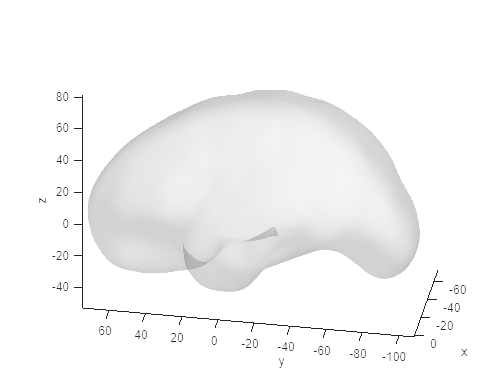

addpath("dataset\")
addpath("priv\")
load('simulation_points_MNI.mat','f_hull','v_hull')

hull_minmax = [-min(v_hull);max(v_hull)];
%v_hull = v_hull+hull_minmax(1,:);

h=mvis(v_hull,f_hull); hold on; clim([0 1]); view([-100 -30])
h.FaceAlpha = .2;
camlight;

clear f_hull v_hull

Defining ranges

WARNING: Not every combination is available, double check before calling it

curvatures = (1:2);
seeds = (1:57);
grid_sizes = [4,8,10,15,18];
iedists = [3,5,10];

Picking electrodes

% Many generally distant electrodes
%chosen_electrodes = {[1,1,5,1],[1,2,3,1],[1,3,1,2],[1,8,3,3],[1,28,1,3],[1,30,1,1],[1,41,2,2]}; model_name = "ManyElectrodes"; 

% Two nearby electrodes
%chosen_electrodes = {[1,2,3,1],[1,41,3,3]}; model_name = "2CloseElectrodes";

% Two almost overlapping electrodes
%chosen_electrodes = {[1,1,5,1],[1,41,3,3]}; model_name = "2OverlappingElectrodes";

% Two curved electrodes
chosen_electrodes = {[2,28,5,1],[2,51,2,2]}; model_name = "2CurvedElectrodes";

ct_name_file = strcat("ct_",model_name);

for i = 1:length(chosen_electrodes)
    mat_file = strcat(  'Curvature',    string(curvatures(chosen_electrodes{i}(1))), ...
                        '-Seed',        string(seeds(chosen_electrodes{i}(2))), ...
                        '-GridSize',    string(grid_sizes(chosen_electrodes{i}(3))), ...
                        '-iedist',      string(iedists(chosen_electrodes{i}(4))), ...
                        '.mat');
    if not(isfile(strcat("dataset/",mat_file)))
        error(strcat("File ",string(i),": ",mat_file," unavailable!"))
    end
end

Writing electrodes

using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 2.2777


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


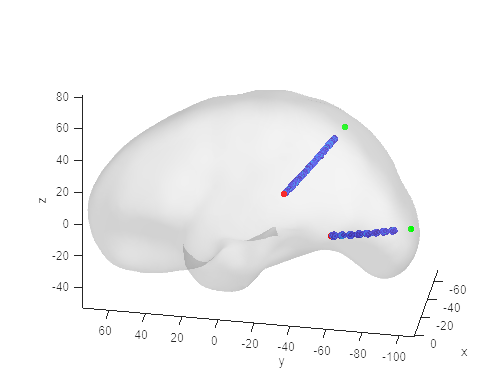

distance target from last point: 1.6197


json_file = fopen(strcat(model_name,'.json'),'w');
electrodes = {};
crdDepths = {};
crdDepthsShifted = {};
weightDepths = {};

rng(42)
for i = 1:length(chosen_electrodes)
    curvature = curvatures(chosen_electrodes{i}(1));
    seed = seeds(chosen_electrodes{i}(2));
    grid_size = grid_sizes(chosen_electrodes{i}(3));
    iedist = iedists(chosen_electrodes{i}(4));
    load(strcat('Curvature',string(curvature),'-Seed',string(seed),'-GridSize',string(grid_size),'-iedist',string(iedist),'.mat'));

    %% Simulate voxels
    options=[];
    options.M1=iedist; %IED
    options.rows =  length(pos_mesh);
    options.cols =  1;
    options.adjMat = makeAdjMat(length(pos_mesh),1);
    options.thresholdValue=-1;
    options.type = 'depth';

    [crdDepth,weightDepth,elecNumDepth]=simulateVoxels(pos_mesh,repmat(normalVecMesh,length(pos_mesh),1),options); %crd: coordinates / weight: voxel weights

    %% Simulate Noise

    options.fractionAdd = 1;
    options.fractionLose = 1;
    options.sigma = .2; %noise level

    options.noiseType = 'intensity_spatial_corr';
    options.noiseDist = 'normal';
    options.repetitions = 1;
    options.thresholdValue = 0;
    options.corr_ratio = .95;
    options.image_res = 0.5;
    options.pos=pos_mesh;

    [crdDepth,weightDepth,elecNumDepth]=addnoise2electrodes(crdDepth,weightDepth,elecNumDepth,options);

    clear elecNumDepth options in_brain_contacts M1

    crdDepthsShifted{1,i} = crdDepth+hull_minmax(1,:);
    crdDepths{1,i} = crdDepth;

    scatter3(crdDepth(:,1),crdDepth(:,2),crdDepth(:,3),5,weightDepth); hold on; axis image;

    % normalize weightDepth
    weightDepth = (weightDepth-min(weightDepth))/(max(weightDepth)-min(weightDepth));
    weightDepths{1,i} = weightDepth;
    
    % target point is considered as a point of the electrode
    % i use the seed point as the entry point
    % and for the target point i use a new point next to the last point
    % picked at a fixed distance
    distTarget = 2;
    % with a bit of a noise
    sigmaTargetPosition = 0.15;

    targetPoint = targetPoint - seedPoint; targetPoint = targetPoint ./ norm(targetPoint);
    targetPoint = pos_mesh(length(pos_mesh),:) + distTarget*targetPoint;
    targetPoint = targetPoint + sigmaTargetPosition*(2*rand(1,3)-1).*(pos_mesh(length(pos_mesh),:)-pos_mesh(length(pos_mesh)-1,:));
  
    scatter3(targetPoint(1,1),targetPoint(1,2),targetPoint(1,3),30,"red","filled")
    scatter3(seedPoint(1,1),seedPoint(1,2),seedPoint(1,3),30,"green","filled")
    
    disp(strcat("distance target from last point: ",string(norm(targetPoint - pos_mesh(length(pos_mesh),:)))))
    
    electrode = struct("iedist",iedist, ...
        "numContacts",grid_size, ...
        "entryPoint",seedPoint, ...
        "targetPoint",targetPoint, ...
        "intermediaryPoints",pos_mesh);
    electrodes{1,i} = electrode;
end

fprintf(json_file,'%s',jsonencode(electrodes,PrettyPrint=true));
fclose(json_file);

clear electrode electrodes json_file sigmaTargetPosition

Voxelizing

ratios = sum(hull_minmax,1);
definitionsRatios = ratios/min(ratios);
definition = round(definitionsRatios*400);

PixelSize = sum(hull_minmax,1)./definition;
maxValueFromExample = 3071;

VoxelizedElectrodes = zeros(definition,"single");
collisionsList = {};
for j = 1:length(crdDepthsShifted)
    crdDepthShifted = crdDepthsShifted{1,j};
    weightDepth = round(weightDepths{1,j}*maxValueFromExample);
    for i = 1:length(crdDepthShifted)
        toVoxel = floor(crdDepthShifted(i,:)./PixelSize);
        found = false;
        for j = 1:height(collisionsList)
            if all(collisionsList{j,1} == toVoxel)
                collisionsList{j,2} = [collisionsList{j,2},weightDepth(i)];
                found = true;
            end
        end
        if not(found)
            if VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)) == 0
                VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)) = weightDepth(i);
            else
                collisionsList{height(collisionsList)+1,1} = toVoxel;
                collisionsList{height(collisionsList),2} = [VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)),weightDepth(i)];
            end
        end
    end
end

%% Averaging collisions
for i = 1:height(collisionsList)
    voxel = collisionsList{i,1};
    VoxelizedElectrodes(voxel(1),voxel(2),voxel(3)) = mean(collisionsList{i,2});
end

clear found toVoxel weightDepth ratios definition definitionsRatios i j maxValueFromExample collisionsList voxel

Saving Brain

% Setting infos from previously given CT image
outinfos = niftiinfo("../ct.nii");
outinfos.ImageSize = size(VoxelizedElectrodes);
%outinfos.Version = 'NIfTI1';
%outinfos.Description = "";
outinfos.PixelDimensions = PixelSize;
outinfos.Transform.T(1,1) = PixelSize(1);
outinfos.Transform.T(2,2) = PixelSize(2);
outinfos.Transform.T(3,3) = PixelSize(3);
outinfos.Transform.T(4,1:3) = -hull_minmax(1,:);
outinfos.raw.dim(2:4) = size(VoxelizedElectrodes);
outinfos.raw.pixdim(2:4) = PixelSize;
outinfos.raw.qoffset_x = -hull_minmax(1,1);
outinfos.raw.qoffset_y = -hull_minmax(1,2);
outinfos.raw.qoffset_z = -hull_minmax(1,3);
outinfos.raw.srow_x = outinfos.Transform.T(:,1)';
outinfos.raw.srow_y = outinfos.Transform.T(:,2)';
outinfos.raw.srow_z = outinfos.Transform.T(:,3)';

outinfos.Filename = strcat(ct_name_file,".nii.gz");
if not(isfile(strcat(ct_name_file,".nii.gz")))
    niftiwrite(VoxelizedElectrodes,ct_name_file,outinfos,"Compressed",true)
end
%infos2 = niftiinfo(brain_name_file);

zip(strcat(model_name,".zip"),{convertStringsToChars(strcat(ct_name_file,".nii.gz")),convertStringsToChars(strcat(model_name,".json"))});

delete(strcat(ct_name_file,".nii.gz")); delete(strcat(model_name,".json"));


clear ct_name_file overwrite